# They Sent Men on the Moon

[⇦ Overview](matlab:open('./Overview.m'))

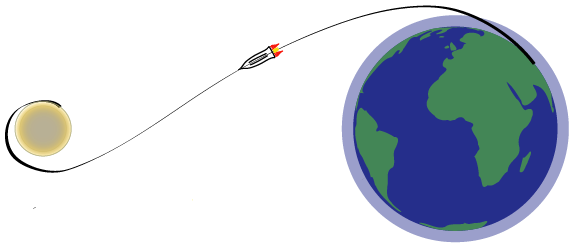

  **Try**. Before to start this script, please fill your name in the following field. This might be used by your professor to check the successful completion of this script.

StudentName = "Valentin Boutrouche ";
MCCGrader(StudentName);

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

`Icon that can be used`

  **Try**.   **Pro-tip**. ** Demonstration**.  **Reflect**. ** Application.**

## Introduction

### The Apollo 11 Mission

From 1961 to 1972, NASA developped a space exploration program named Apollo which principal objective was to be the first space agency to explore the Moon. In 1969, the Apollo 11 mission successfully launch from Cape Canaveral, Florida using a Saturn V rocket. After a couple of revolution around the earth, the spacecraft occupied by astronauts Neil Armstrong, Michael Collins and Buzz Aldrin left earth orbit in direction of the Moon. After achieving the first lunar landing, astronaut Neil Armstron and Buzz Aldrin were the first men to ever set foot on the Moon. Twenty-one hours later, the crew took off from the Moon to rendez-vous with Michael Collins who stayed in orbit before to safely return home.

### The Saturn V Rocket

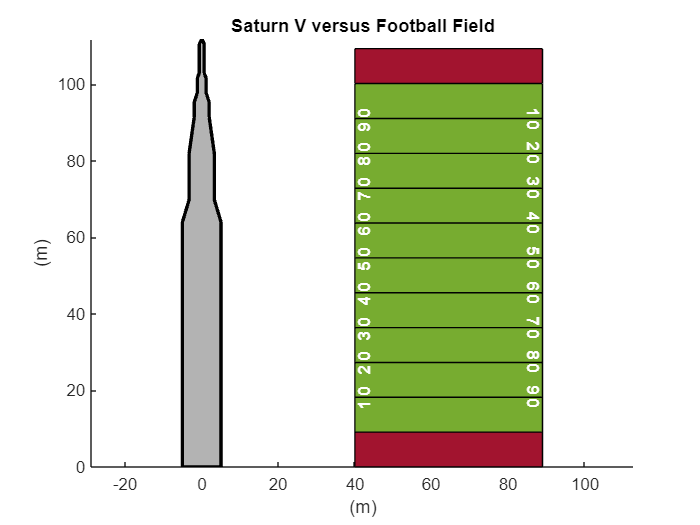

IntroRocket();

## Modelling the launch

In this script, we will apply the integral form of the mass conservation equation and the linear momentum conservation equation to the Saturn V rocket. Our goal here, is to **model the first phase of Apollo 11's launch**. The results from this model should be able to give us the altitude of rocket with respect to time during this acent phase. As first step towards that goal, we are making the following assumption:

- The friction forces along the rocket are negligible compare to the thrust generated by the rockets engines.

- The flight path of the rocket during the first phase is the ascent is purely vertical

### Define Control Volume

The first step of every problem using the integral form of mass and momentum conservation equations is to define the control volume and control surfaces consider for the problem. In the case of the rocket, we are chosing a movin control volume, that is the the rocket.

  **Try**. Use the followin drop down menu to visualize the Control Volume and associated Control Surfaces of the domain.

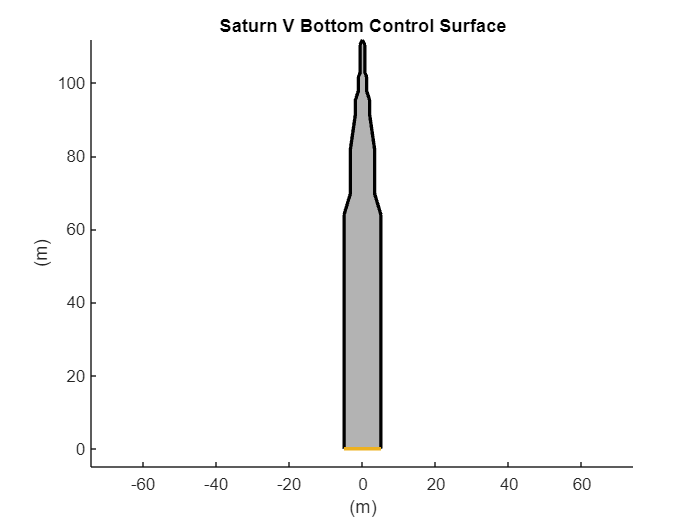

Answer = 4;
IntroControlVolume(Answer)

Solving the mass and momentum conservation equation often involved integration of mass and momentum fluxes through the Control Surfaces. One of the main sources of error in solving this kind of problem come from a poor definition of the normal vector to the Control Surfaces.

  **Try**. Define the direction of the normal vector to the bottom Control Surface of the Control Volume that we just defined.

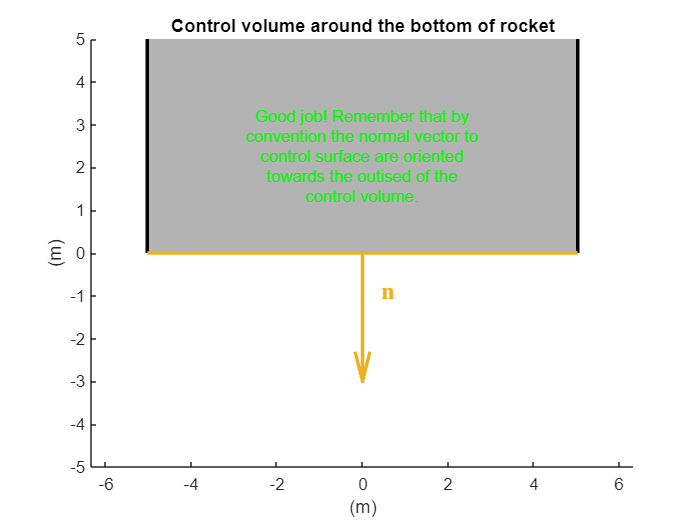

Answer = 2;
cmp = SelectDirectionBottomControlSurface(Answer);

if cmp
    Score = Score + 1;
end

  **Try**. Now that you correctly defined the normal to the bottom Control Volume, try using the following drop-down menu to visualize the normal vector of the other Control Surfaces.

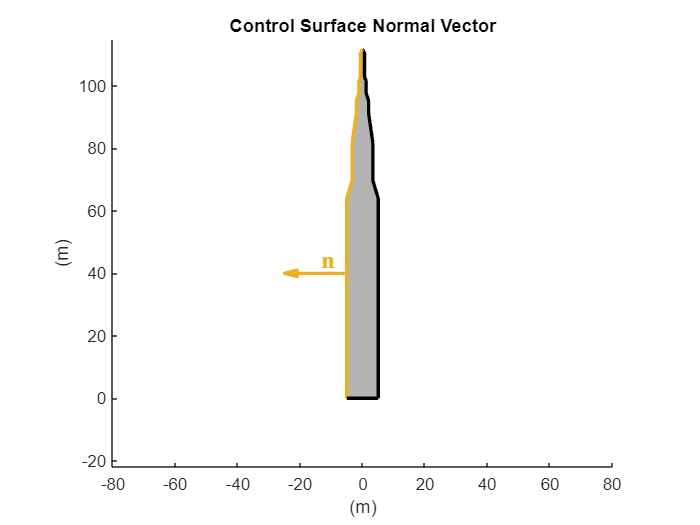

Answer = "LeftControlSurface";
figure()
DrawSaturn(Answer, true, "NormalVector", true);
title("Control Surface Normal Vector")
xlim([-80 80])
ylim([-22 115])

### Apply Conservation of Mass

Now the Control Volume and the Control Surfaces were defined, we can start applying conservation law. The Mass Conservation equation is often time the first one to be applied to fluid dynamics problem, mainly because its constituing terms are usually simpler to compute than the one present in the conservation of momentum and energy. Remember that the mass conservation equation applied to a Control Volume is as follow:


$$\frac{\partial}{\partial t}\int_{CV}\rho dV+\int_{CS} ({\bf u}\cdot{\bf n})\rho dS = 0$$


In the case of the the domain that we defined in the previous section, the mass flux integral over the Control Surfaces can be broken down into three integral over the right, left and bottom Control Surfaces:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho dV}_\text{A}
+
\underbrace{\int_{CS_{right}} ({\bf u}\cdot{\bf n})\rho dS }_\text{B}
+
\underbrace{\int_{CS_{left}} ({\bf u}\cdot{\bf n})\rho dS }_\text{C}
+
\underbrace{\int_{CS_{bottom}} ({\bf u}\cdot{\bf n})\rho dS }_\text{D}
= 0$$


  **Pro-tip**. In most fluid dynamics problem, the first step towards solving the problem consists in simplifying the equation rather than actually performing the integration. In the case of the Mass Conservation equation, we should be looking for the negligible or null mass flux.

  **Try**. Which one of the term in equation (XXX) is null?

A = false; B = true; C = true; D = false;
Answer = [A; B; C; D];
 
cmp = CheckNullTermMassConservation(Answer);

Good Job you identified the null term correctly!


if cmp
    Score = Score + 1;
end

That being done, we can start developping the other term in the equation (XXX), starting with term A.

  **Try**. What is term A equal to?


$$\text{1) } \frac{\partial m(t)}{\partial t} 
\quad\quad
\text{2) } {\bf u}\cdot \frac{\partial m(t)}{\partial t}
\quad \quad
\text{3) } u_e \frac{\partial m(t)}{\partial t}
\quad \quad
\text{4) } \frac{\partial m(t)\times t}{\partial t}$$


Answer = 1;
cmp = CheckFirstTermMassConservation(Answer);

Good job!


if cmp
    Score = Score + 1;
end

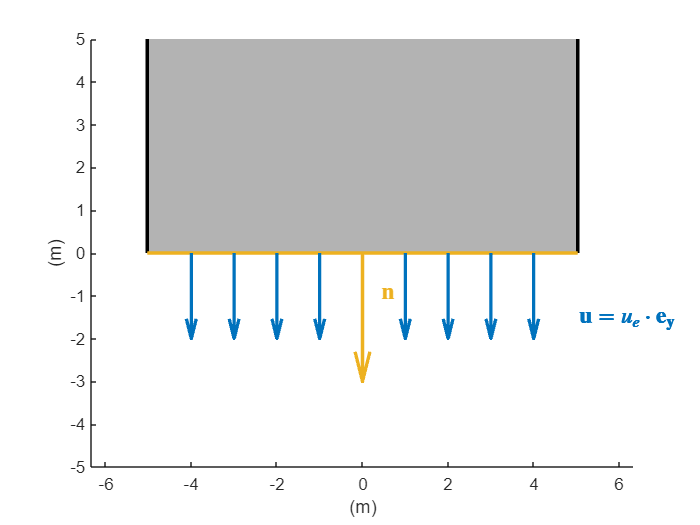

figure()
ax = DrawSaturn("BottomControlSurface", true, "FocusBottom", true, "NormalVector", true, "ExhaustVelocity", true, "ExhaustVelocityText", true);

  **Try**. Which one of this assumption is true?


$$\text{1) }{\bf u}\cdot{\bf n} = -u_e
\quad\quad
\text{2) }{\bf u}\cdot{\bf n} = u_e$$


Answer = 1;
cmp = CheckNormalDotVelocity(Answer);

Good Job! The vector have the same direction to their scalar product is positive.


if cmp
    Score = Score + 1;
end

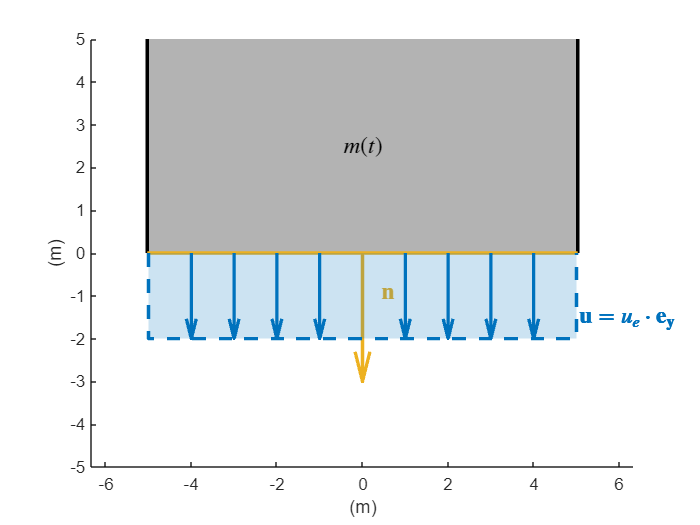

figure()
ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", true, ...
    "ExhaustVelocity", true, "ExhaustMassFlow", true , ...
    "ExhaustVelocityText", true, "MassText", true);

In the previous figure, the highlighted area represent the value of the remaining integral in the Mass Conservation equation:


$$\frac{\partial m(t)}{\partial t}
+\int_{CS_{bottom}} \rho u_e dS
= 0$$


  **Try**. What is the value of the remaining integral in equation (XXX)?


$$\text{1) } {\bf u}\cdot\dot{m_e}
\quad\quad
\text{2) } -u_e\dot{m_e} 
\quad\quad
\text{3) } \dot{m_e}
$$


Q = 3;
Q = Q == 3;
if Q
    disp("Yes, 3 is the right answer!")
else
    warning("The answer to this question is wrong")
end

Yes, 3 is the right answer!


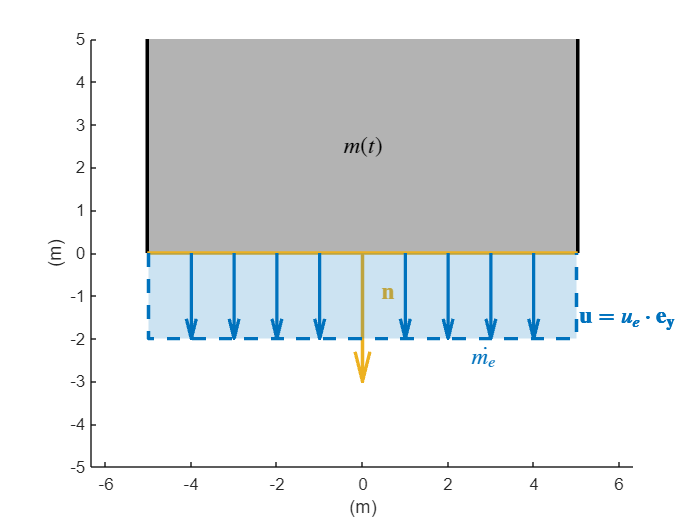

figure()
ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", true, ...
    "ExhaustVelocity", true, "ExhaustMassFlow", true , "ExhaustMassFlowText", true, ...
    "ExhaustVelocityText", true, "MassText", true);

The final differential equation obtained from the mass conservation equation is the following: 


$$\frac{\partial m(t)}{\partial t} = -\dot{m_e}$$


The solution of the differential is of the form: $m(t) = -\dot{m_e}   t + C$

We can define a value of the constant integration $C$by considering the initial mass of the rocket $m_0$ at $t = 0
$.


$$m(t) = m_0 - \dot{m_e}t$$


In the case of the Saturn V rocket for the Apollo 11 mission, the initial mass of the rocket was 2,950,000 kg and the total mass flow out of the five F-1 engine totaled at 12,600 kg/s.

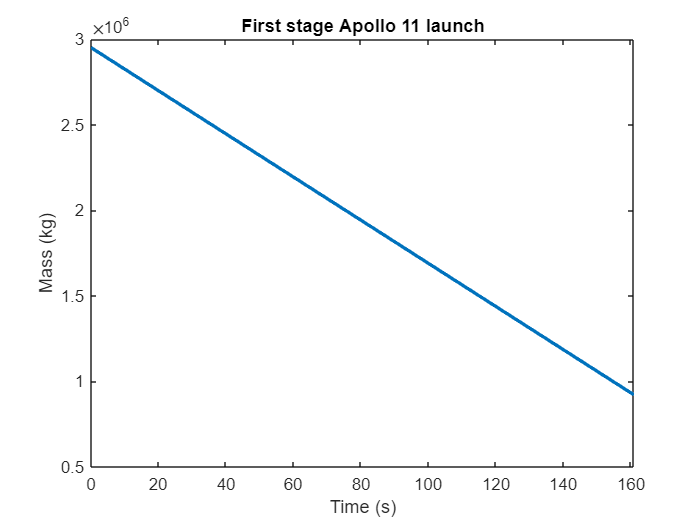

t = linspace(0,161,2);
m0 = 2950000;
me = 12600;
m = @(t) m0 - me*t;
plot(t,m(t),"SeriesIndex",1, "LineWidth",2)
xlabel("Time (s)")
ylabel("Mass (kg)")
title("First stage Apollo 11 launch")
xlim([0 161])

 **Reflect**. The amount of rocket fuel used during the first phase of the launch represent emptying 200 regular car tank every second during the 161 seconds of the first phase, almost 34,000 cars. 

### Apply Conservation of Momentum

XXX Comment about Mass conservation equation

figure()
ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", true, ...
    "ExhaustVelocity", true, "ExhaustMassFlow", true , "ExhaustMassFlowText", true, ...
    "ExhaustVelocityText", true, "MassText", true);

The Mass Flux exiting the rocket engine is generating the force that is setting the rocket in motion.

  **Try**. What is the direction of the thrust force applied on the rocket?

Answer = 1;
cmp = CheckThrustDirection(Answer);

Good Job! The resulting thrust is in the opposite direction of the exhaust velocity.


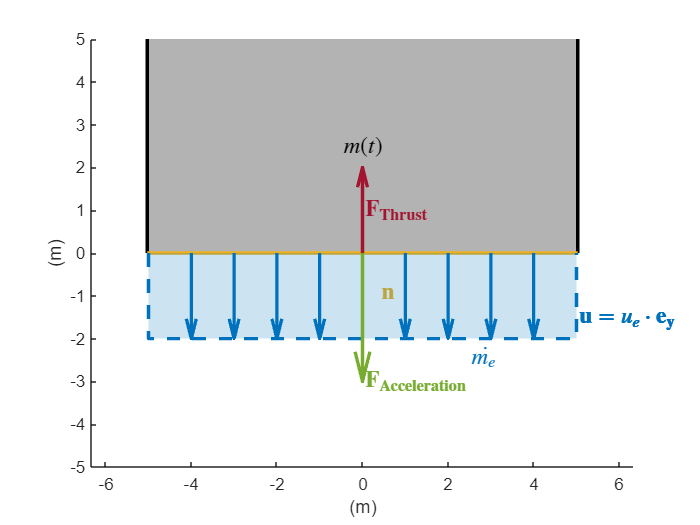

if cmp
    Score = Score + 1;
    figure()
    ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", true, ...
    "ExhaustVelocity", true, "ExhaustMassFlow", true , "ExhaustMassFlowText", true, ...
    "ExhaustVelocityText", true, "MassText", true, "Thrust", true, "Acceleration", true);
end

The Momentum Conservation equation is usually expressed as follow:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV}_\text{Acceleration}
+
\underbrace{\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS}_\text{Thrust}
=
\Sigma {\bf F}$$


#### Derivation of the Acceleration Term

First, we should integration the acceleration term in XXX

  **Pro-tip**. All of the velocity are considered with respect to the moving reference frame that is our Control Volume.

  **Pro-tip**. In order to consider this equation (XXX) for an accelerating Control Volume, we includes the acceleration of the control Volume as a forces acting on the Control Volume.

  **Try**. What is the direction of the resulting force acting on the Control Volume?

Answer = 2;
cmp = CheckAccelerationResultantControlVolume(Answer);

Good job! Resulting forces are always directed in the opposite direction of their sources.


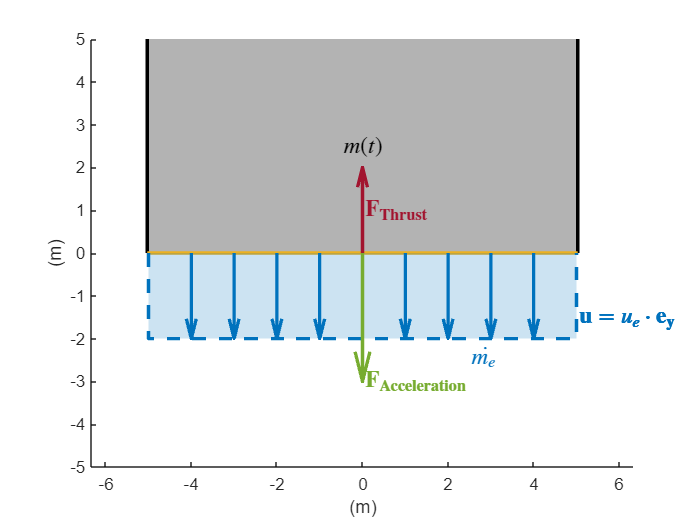

if cmp
    Score = Score + 1;
    figure()
    ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", false, ...
    "ExhaustVelocity", true, "ExhaustMassFlow", true , "ExhaustMassFlowText", true, ...
    "ExhaustVelocityText", true, "MassText", true, "Thrust", true, "Acceleration", true);
end

  **Try**. What other forces apply to our Control Volume?

Answer = [];
Answer(1) = true;
Answer(2) = false;
Answer(3) = false;
Answer(4) = true;
Answer(5) = false;
Answer(6) = false;
 
cmp = CheckAppliedForces(Answer);

Good job! In our case, only air resistance and gravity applies.


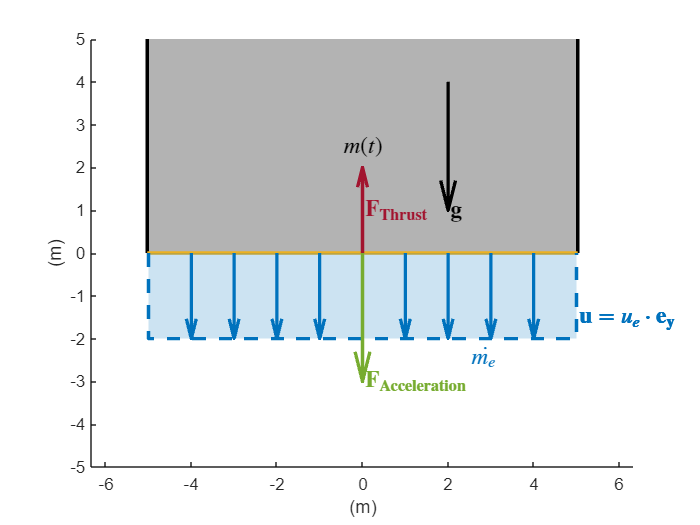

if cmp
    Score = Score + 1;
    figure()
    ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", false, ...
    "ExhaustVelocity", true, "ExhaustMassFlow", true , "ExhaustMassFlowText", true, ...
    "ExhaustVelocityText", true, "MassText", true, "Thrust", true, "Acceleration", true, ...
    "Gravity", true);
end


$$\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS
=
m(t){\bf g} - m(t){\bf a_{CV}}$$


We can XXX the equation along the vertical axis:


$$\frac{\partial}{\partial t}\int_{CV}\rho({\bf u}\cdot{\bf e_y})dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
=
m(t){\bf g}\cdot{\bf e_y} - m(t){\bf a_{CV}}\cdot{\bf e_y}$$



$$\frac{\partial}{\partial t}\int_{CV}\rho({\bf u}\cdot{\bf e_y})dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
=
-m(t)g - m(t)\frac{\partial^2 y_\text{CV}}{\partial y^2}$$


We already know the definition of $m(t)$ from applying the Mass Conservation equation to the Control Volume. The gravity $g$ is considered constant equal to 9.81 $\text{m/s}^2$. The altitude of the Control Volume is equivalent to the altidue of the rocket and is actuall what we are looking to define here.

**Assumption: **The acceleration term due to mass flow inside the Control Volume is neglected. It assume that this term is negligible compare to the thrust generated by the rocket.

Therefore, the last term to consider here is the integral thrust term.

#### Derivation of the Thrust Term

Just like we did for the Mass Conservation equation, we are breaking down the integral over the Control Surfaces over three integral over each of the Control Surfaces:


$$\int_{CS}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
=
\int_{CS_\text{right}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
+
\int_{CS_\text{left}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
+
\int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS$$


  **Try**. Which integral term along the Control Surfaces is equal to zero?

Answer = [];
Answer(1) = true; 
Answer(2) = true; 
Answer(3) = false; 
 
cmp = CheckNullTermMomentumConservation(Answer);

Good job! You found all of the term equal to zero.


if cmp
    Score = Score + 1;
end

figure()
ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", true, ...
    "ExhaustVelocity", true, "ExhaustMassFlow", true , "ExhaustMassFlowText", true, ...
    "ExhaustVelocityText", true, "MassText", true);


$$\int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS 
=
\int_{CS_\text{bottom}} (?) u_e \rho u_e dS
$$


  **Try**. What is the sign resulting from the two scalar product $(+)$ or $(-)
$?

Answer = 2;
cmp = CheckSignThrustTerm(Answer);

Good job!


if cmp
    Score = Score + 1;
end

  **Try**. Considering that the velocity along the bottom Control Surface is uniform, and the following results from the Mass Conservation $\int_{CV_\text{bottom}}\rho u_e dS = \dot{m_e}$, what is the final expression of the thrust term along the bottom Control Surface?

- 
$$u_e^2 \dot{m_e}$$


- 
$$-u_e\dot{m_e}$$


- 
$$-\dot{m_e}$$


- 
$$-u_e^2$$


Answer = [];
Answer(1) = false; Answer(2) = true; Answer(3) = false; Answer(4) = false;
 
cmp = CheckThrustTerm(Answer);

Good job!


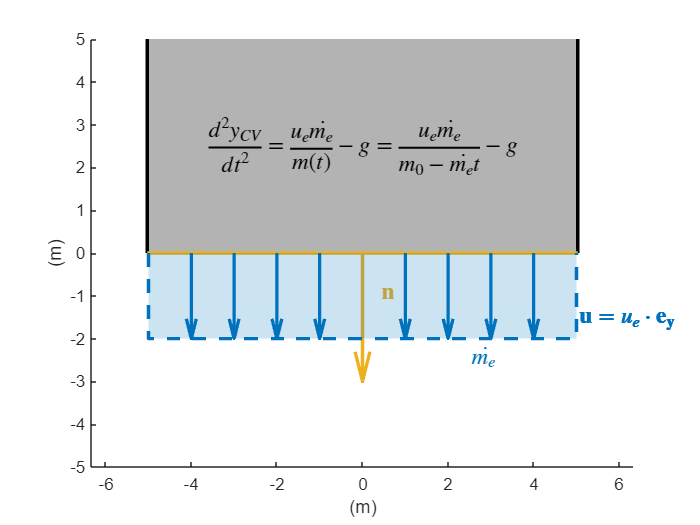

if cmp
    figure()
    ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", true, ...
    "ExhaustVelocity", true, "ExhaustMassFlow", true , "ExhaustMassFlowText", true, ...
    "ExhaustVelocityText", true);
    text(0.0, 2.5, "$\frac{d^2 y_{CV}}{d t^2} = \frac{u_e\dot{m_e}}{m(t)}-g = \frac{u_e\dot{m_e}}{m_0-\dot{m_e}t}-g$", "Interpreter", "latex", "HorizontalAlignment","center", ...
        "VerticalAlignment", "middle", "FontSize", 14)
    Score = Score + 1;
end

## Compare Results to Real Flight Log Data From Apollo 11 Mission

load ApolloFlightLog.mat

Error using load
'ApolloFlightLog.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\vboutrou\OneDrive - MathWorks\Documents\MATLAB\MCC\fluid-mechanics\InternalFiles\data

Change the MATLAB current folder or add its folder to the MATLAB path.


tiledlayout(3,1)
nexttile
plot(Apollo.t, Apollo.Altitude/1000, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel("Altitude (km)")
nexttile
plot(Apollo.t, Apollo.Velocity, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel("Velocity (m/s)")
nexttile
plot(Apollo.t, Apollo.Acceleration, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel('Acceleration (m/s^2)')
xlabel('Flight Time (s)')

 **Reflect**.  

## Causes of inacurracy

### Frictions Forces

[Insert control volume image with friction forces]

### Non-vertical flight path

In the previous section, we consider that the trust of the rocket was directed verticaly and therefore the flight path of the rocket should be purely vertical. However, the flight path of Apollo 11 was not directed directly verticaly. The mission consisted a getting the spacecraft into earth orbit for a couple of revolution before the start the translunar injection.

figure()
ax = DrawSaturn("PathAngle", 20);

Bla Blah Bla about the total trajectory

 
load Trajectory.mat
uif = uifigure();
gg = geoglobe(uif);
geoplot3(gg,Flight.Lat,Flight.Lon,Flight.El,'y','HeightReference','terrain', 'LineWidth',3)

## Improvement of the model

### Correction for rocket flight path angle

Show back the ODE from the vertical climb:

Ask question about how the acceleration term is modify:


$$\frac{\partial^2y(t)}{\partial t^2}=cos(\alpha(t))\frac{\dot{m_e}u_e}{m_o-\dot{m_e}t} - g$$


Plot Angle of ascend

alpha = @(t) interp1(Path.t, Path.Angle, t, 'pchip');
me    = 2180000/161;
m0    = 2950000;
Isp   = 281;
m     = @(t) m0 - me*t;
g     = 9.81;
ue    = Isp * g;

dudt = @(t,y) cosd(alpha(t))*me*ue/m(t)-g;
[tSol,uSol] = ode45(dudt, [0 161], 0);
plot(tSol,uSol)
dydt = @(t,y) interp1(tSol,uSol, t, 'pchip');
[tSol2,ySol] = ode45(dydt, [0 161], 0);
plot(tSol2, ySol)

### Adding the friction forces

#### Wind tunnel experimentation of Saturn V aerodynamic

Talk about wind tunnel?

Identify the parameter of the problem?

What are the repeating parameter?

Define the Mach Number:

Define friction coefficient:

#### New ODE

#### Define the atmosphere surrounding the rocket

Question about the equation of fluid statics?

Question about the density?

Question about equation of state?

Final equation

Present the ISA, ICAO etc atmosphere

Show the function

#### Solve ODE with friction

## Conclusion

  **Pro-tip**. If your professore is requiring you to submit your completed script back, please make sure to add your name in the top of this file.

## Feedbacks

If you wish to provide feebacks to the developper, the developper provides three ways of reaching out:

- MATLAB File Exchange

- GitHub

- Email

If this script is used as an assigment by your professor and you wish to leave him feeback, you can add them to the following fieds, those feedbacks will stay in between you and your professor.

""

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function ax = DrawSaturn(varargin)

    % Input Parameter:
    PathAngle      = 0;
    lComparison    = false;
    lControlVolume = false;
    lRightControlSurface = false;
    lLeftControlSurface = false;
    lBottomControlSurface = false;
    lNormalVector = false;
    lGravity = false;
    lFocusBottom = false;
    lExhaustVelocity = false;
    lExhaustMassFlow = false;
    lExhaustVelocityText = false;
    lExhaustMassFlowText = false;
    lMassText = false;
    lThrust = false;
    lAcceleration = false;

    % Read the varargin
    nargin = size(varargin,2);
    for n = 1:nargin
        if ( isstring(varargin{n}) || ischar(varargin{n}) )
            switch (varargin{n})
                case "Comparison"
                    lComparison = varargin{n+1};
                case "ControlVolume"
                    lControlVolume = varargin{n+1};
                case "RightControlSurface"
                    lRightControlSurface = varargin{n+1};
                case "LeftControlSurface"
                    lLeftControlSurface = varargin{n+1};
                case "BottomControlSurface"
                    lBottomControlSurface = true;
                case "PathAngle"
                    PathAngle = varargin{n+1};
                case "NormalVector"
                    lNormalVector = varargin{n+1};
                case "Gravity"
                    lGravity = varargin{n+1};
                case "FocusBottom"
                    lFocusBottom = varargin{n+1};
                case "ExhaustVelocity"
                    lExhaustVelocity = varargin{n+1};
                case "ExhaustMassFlow"
                    lExhaustMassFlow = varargin{n+1};
                case "ExhaustVelocityText"
                    lExhaustVelocityText = varargin{n+1};
                case "ExhaustMassFlowText"
                    lExhaustMassFlowText = varargin{n+1};
                case "MassText"
                    lMassText = varargin{n+1};
                case "Thrust"
                    lThrust = varargin{n+1};
                case "Acceleration"
                    lAcceleration = varargin{n+1};
            end
        end
    end

    % Define the axis:
    ax = axes;
    xlabel(ax, "(m)")
    ylabel(ax, "(m)")
    axis equal
    hold on
    ColorHighlight = ax.ColorOrder(3,:);

    % Plot rocket:
    xR = [ 0 5.0292 5.0292 3.302 3.302 1.9558 1.9558 1.143 1.143 0.635 0.635 0];
    yR = [ 0 0 63.9826 69.7484 81.838 91.313 95.2246 97.7646 101.6 102.87 110.49 111.76];
    if ~lControlVolume
        patch( xR, yR, [0.7 0.7 0.7], "EdgeColor", "none")
        patch(-xR, yR, [0.7 0.7 0.7], "EdgeColor", "none")
    else
        patch( xR, yR, ColorHighlight, "EdgeColor", "none")
        patch(-xR, yR, ColorHighlight, "EdgeColor", "none")
    end

    % Right Control Surface
    if ~lRightControlSurface
        line( xR(2:end),yR(2:end),"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line( xR(2:end),yR(2:end),"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
    end

    % Left Control Surface
    if ~lLeftControlSurface
        line( -xR(2:end),yR(2:end),"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line( -xR(2:end),yR(2:end),"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
    end

    % Bottom Control Surface
    if ~lBottomControlSurface
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
    end
    
    % Draw football field
    if lComparison
        xF = [40 89 89 40];
        yF = [0 0 9.1 9.1];
        patch(xF,yF, ax.ColorOrder(7,:))
        for i = 1:10
            yF = yF + 9.1;
            patch(xF,yF,ax.ColorOrder(5,:))
            if i ~= 1
                text(42.5, (i*10)*0.91, sprintf("%i 0", i-1), "Rotation",90,"Color","w","HorizontalAlignment","center","FontWeight","bold")
                text(86.5, (i*10)*0.91, sprintf("%i 0", 11-i), "Rotation",-90,"Color","w","HorizontalAlignment","center","FontWeight","bold")
            end
        end
        yF = yF + 10*0.9144;
        patch(xF,yF,ax.ColorOrder(7,:))
    end
    
    if lNormalVector
        lVec = [lRightControlSurface; lLeftControlSurface; lBottomControlSurface];
        if ~lFocusBottom
            xPos = [xR(2) -xR(2) 0.0; 40.0 40.0 0.0; 0.0 0.0 0.0];
            xDir = [20 -20 0.0; 0.0 0.0 -20.0; 0.0 0.0 0.0];
        else
            xPos = [xR(2) -xR(2) 0.0; 2.0 2.0 0.0; 0.0 0.0 0.0];
            xDir = [3 -3 0.0; 0.0 0.0 -3; 0.0 0.0 0.0];
        end
        for s = 1:3
            if lVec(s)
                xy = rotz(-PathAngle)*xPos(:,s);
                uv = rotz(-PathAngle)*xDir(:,s);
                quiver( xy(1), xy(2), uv(1), uv(2), 0.0, "AutoScale", "off", "LineWidth", 2, "Color", ColorHighlight, "MaxHeadSize", 0.7);
                text(xy(1)+0.5*uv(1)+0.2*norm(uv), xy(2)+0.5*uv(2)+0.2*norm(uv), "${\bf n}$", "Interpreter","latex", ...
                    "HorizontalAlignment","center", "Color",ColorHighlight, "Rotation",-PathAngle, "FontSize", 14)
            end
        end
    end

    if lExhaustVelocity & lFocusBottom
        for i = 1:4
            quiver( i, 0.0, 0, -2, 0.0, "AutoScale", "off", "LineWidth", 2, "Color", ax.ColorOrder(1,:), "MaxHeadSize", 0.7);
            quiver( -i, 0.0, 0, -2, 0.0, "AutoScale", "off", "LineWidth", 2, "Color", ax.ColorOrder(1,:), "MaxHeadSize", 0.7);
            if lExhaustVelocityText
                text(5.0, -1.5, "${\bf u} = u_e\cdot{\bf e_y}$", "Interpreter", "latex", "FontSize",14, "Color", ax.ColorOrder(1,:))
            end
        end
    end

    if lExhaustMassFlow & lFocusBottom
        patch([-5 5 5 -5], [-2 -2 0 0], ax.ColorOrder(1,:), "FaceAlpha", 0.2, "LineStyle", "none")
        line([-5 -5 5 5], [0 -2 -2 0], "Color",ax.ColorOrder(1,:), "LineStyle", "--", "LineWidth", 2)
        if lExhaustMassFlowText
            text(2.5, -2.4, "$\dot{m_e}$", "Interpreter", "latex", "FontSize",14, "Color", ax.ColorOrder(1,:))
        end
    end    
    
    if PathAngle ~= 0
        line([0 0], [-10 130], "LineStyle","-.", "Color", "k")
        hl = line([0 0], [0 yR(end)+20], "LineStyle", "-.","Color", "k");
        rotate(hl, [0 0 1], PathAngle, [0 yR(end) 0])
        i = linspace(0,PathAngle, 100);
        x = 80*cosd(i-90);
        y = 80*sind(i-90)+yR(end);
        hold on
        plot(x,y, "k-")
        text(mean(x), mean(y)-4, "$\alpha$", "Interpreter", "latex", "FontSize",14)    
        child = allchild(ax);
        rotate(child, [0 0 1], -PathAngle, [0 0 0])
    end

    if lMassText
        text(0.0, 2.5, "$m(t)$", "Interpreter","latex","HorizontalAlignment","center", "FontSize",14)
    end
   
    if lThrust
        xPos = [0.0 0.0];
        if lFocusBottom
            xDir = [0.0 2.0];
        else
            xDir = [0.0 20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color",ax.ColorOrder(7,:), "MaxHeadSize",0.7)
        text(xPos(1)+0.5*xDir(1), xPos(2)+1.0, "${\bf F_{Thrust}}$", "Interpreter","latex","Color",ax.ColorOrder(7,:), "FontSize",14)
    end

    if lAcceleration
        xPos = [0.0 0.0];
        if lFocusBottom
            xDir = [0.0 -3.0];
        else
            xDir = [0.0 -20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color",ax.ColorOrder(5,:), "MaxHeadSize",0.7)
        text(xPos(1), xPos(2)+xDir(2), "${\bf F_{Acceleration}}$", "Interpreter","latex","Color",ax.ColorOrder(5,:), "FontSize",14)
    end

    if lGravity
        xPos = [2.0 4.0];
        if lFocusBottom
            xDir = [0.0 -3.0];
        else
            xDir = [0.0 -20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color", "k", "MaxHeadSize",0.7)
        text(xPos(1), xPos(2)+xDir(2), "${\bf g}$", "Interpreter","latex","Color", "k", "FontSize",14)
    end

    hold off

    if lFocusBottom
        ylim([-5 5])
    end
end


function rho = atmDensity(yq, Standard, R)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq,0.0)} % Altitude in meter
        Standard string {mustBeMember(Standard,["ISA","ICAO"])} = "ISA"
        R double {mustBePositive} = 287.0528 % Specific gas constant
    end
    % P = rho*R*T
    P = atmPressure(yq, Standard, R);
    T = atmTemp(yq, Standard);
    % Solution:
    rho = P ./ (R*T);
end

function T = atmTemp(yq, Standard)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq, 0.0)}
        Standard string {mustBeMember(Standard, ["ISA", "ICAO"])} = "ISA"
    end
    % Define the atmosphere:
    if     Standard == "ISA"
        y_Standard = [-610 11000 20000 32000 47000 51000 71000 84852];
        T_Standard = [19 -56.5 -56.5 -44.5 -2.5 -2.5 -58.5 -86.28]+273.15;
    elseif Standard == "ICAO"
        y_Standard = [0 11000 20000 32000];
        y_Standard = [15 -56.5 -56.5 -44.5]+273.15;
    end
    % Solution:
    T = interp1(y_Standard,T_Standard, yq, "linear");
end

function P = atmPressure(yq, Standard, R)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq, 0.0)}
        Standard string {mustBeMember(Standard, ["ISA", "ICAO"])} = "ISA"
        R double {mustBePositive} = 287.0528 % Specific gas constant
    end
    % dP/dy = - P/(RT) g
    T = @(y) atmTemp(y, Standard);
    dPdy = @(y,P) -P/(R*T(y))*9.81;
    [ySol,PSol] = ode45(dPdy, [0.0 yq(end)], 101325);
    % Solution:
    P = interp1(ySol,PSol,yq);
end

function IntroRocket()
    figure()
    DrawSaturn("Comparison", true);
    title("Saturn V versus Football Field")
    MCCGrader(true);
end

function IntroControlVolume(Item)
    figure()
    switch Item
        case 0
            DrawSaturn();
            title("Saturn V without highlight")
        case 1
            DrawSaturn("ControlVolume", true);
            title("Saturn V Control Volume")
        case 2
            DrawSaturn("RightControlSurface", true);
            title("Saturn V Right Control Surface")
        case 3
            DrawSaturn("LeftControlSurface", true);
            title("Saturn V Left Control Surface")
        case 4
            DrawSaturn("BottomControlSurface", true);
            title("Saturn V Bottom Control Surface")
    end
    ylim([-5 112])
end

function cmp = SelectDirectionBottomControlSurface(Direction)
    figure()
    cmp = false;

    if Direction ==0
        ax   = DrawSaturn("FocusBottom", true, "BottomControlSurface", true);
        txt  = "Please selecte either Upward or Downward.";
        ctxt = "r";
    elseif Direction == 1
        ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true);
        hold on 
        quiver(0,0,0,3,0,"AutoScale","off","MaxHeadSize",0.7,"Color", ax.ColorOrder(3,:), "LineWidth",2)
        hold off
        txt = "Wrong! Remember that by convention the normal vector to control surface are oriented towards the outised of the control volume.";
        ctxt = "r";
    elseif Direction == 2
        ax = DrawSaturn("FocusBottom", true, "BottomControlSurface", true, "NormalVector", true);
        txt = "Good job! Remember that by convention the normal vector to control surface are oriented towards the outised of the control volume.";
        cmp = true;
        ctxt = "g";
    end
    boxPos = ax.Position;
    boxPos([1 3]) = boxPos([1 3]) + [0.2 -0.4];
    boxPos([2 4]) = [0.6 0.2]; 
    annotation("textbox", boxPos, "String", txt, "HorizontalAlignment","center", ...
               "VerticalAlignment","middle", "EdgeColor","none","Color",ctxt)
    title("Control volume around the bottom of rocket")
end

function cmp = CheckNullTermMassConservation(Answer)
    if (~Answer(1) & Answer(2) & Answer(3) & ~Answer(4))
        disp("Good Job you identified the null term correctly!")
        cmp = true;
    else
        warning("There is at least one wrong answer, in this case the only null term should be terms where there is no mass flux throught the surface!")
        cmp = false;
    end
end

function cmp = CheckFirstTermMassConservation(Answer)
    if Answer == 1
        disp("Good job!")
    elseif Answer == 0
        warning("Wrong! One of the answer is correct! Try again!")
    else
        warning("Wrong! Try again!")
    end
    cmp = Answer == 1;
end

function cmp = CheckNormalDotVelocity(Answer)
    cmp = Answer == 2;
    if Answer == 0
        warning("Wrong! At least one of the two other option is correct!")
    elseif Answer == 1
        disp("Good Job! The vector have the same direction to their scalar product is positive.")
    else
        warning("Wrong! Try again considering the direction of the vector with respect to each other.")
    end
end

function cmp = CheckThrustDirection(Answer)
    cmp = Answer == 1;
    if Answer == 0
        warning("Wrong! The resulting thrust is parallel to the exhaust velocity! Try Again!")
    elseif Answer == 1
        disp("Good Job! The resulting thrust is in the opposite direction of the exhaust velocity.")
    elseif Answer == 2
        warning("Wrong! The thrust is parallel to the exhaust velocity, but your direction is wrong.")
    end
end

function cmp = CheckAccelerationResultantControlVolume(Answer)
    cmp = Answer == 2;
    if Answer == 0
        warning("Wrong! The resulting force due to the acceleration of the Control Volume is parallel to the velocity of the Control Volume! Remember that our rocket is flying verticaly. Try again!")
    elseif Answer == 1
        warning("Wrong! Remember that the direction of resulting forces is always opposite to the direction of its source, just like the thrust was upward while the mass flow is going downward. Try Again!")
    elseif Answer == 2
        disp("Good job! Resulting forces are always directed in the opposite direction of their sources.")
    end
end

function cmp = CheckAppliedForces(Answer)
    cmp = Answer == [true false false true false false];
    if cmp
        disp("Good job! In our case, only air resistance and gravity applies.")
    else
        if Answer(6)
            warning("Wrong! The Thrust should not be included in the body and surface forces count, as it is already being taking into account in the integral term over the Control Surfaces!")
        else
            warning("Wrong! You got at least one answer wrong, try again!")
        end
    end
end

function cmp = CheckNullTermMomentumConservation(Answer)
    cmp = Answer == [true true false];
    if cmp
        disp("Good job! You found all of the term equal to zero.")
    else
        warning("Wrong! There is at least one error, remember the results from the same question applied to the mass conservation equation.")
    end
end

function cmp = CheckSignThrustTerm(Answer)
    cmp = Answer == 2;
    if Answer == 0
        warning("Please select either Positive or Negative sign.")
    elseif Answer == 1
        warning("Wrong! Be careful about the direction of the vectors. Try again!")
    else
        disp("Good job!")
    end
end

function cmp = CheckThrustTerm(Answer)
    cmp = Answer == [false true false false];
    if cmp
        disp("Good job!")
    else
        warning("Wrong! Try again!.")
    end
end




[⇦ Return to the navigation page](matlab: OpenOverview)